# Solve System of Nonlinear Equations

Do not edit. This code defines and plots the implicit functions for the circle and hyperbola.

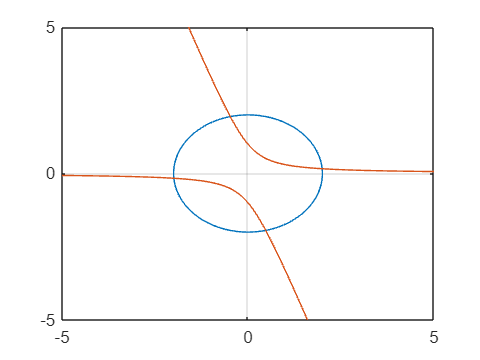

myCirc = @(x,y) x.^2 + y.^2 - 4;
myHyp = @(x,y) y.^2 + 3*x.*y - 1;
fimplicit(myCirc,[-3 3])
hold on
fimplicit(myHyp)
hold off
grid on

## Task 1

In this activity, you'll find a solution to the system of equations given by

x2+y2=4

y2+3xy=1. 

The equations have been plotted for you.

Task

Create a function handle `rootFunction` to an anonymous function with one input which represents the system 

x2+y2−4=0

y2+3xy−1=0.

Implicit functions for the equations are stored in the function handles `myCirc` and `myHyp`.

In the function definition, keep the equations in the order given, i.e.,  the circle is the first equation and the hyperbola the second. 

rootFunction=@(w)[myCirc(w(1),w(2));
    myHyp(w(1),w(2))]

rootFunction = function_handle with value:
    @(w)[myCirc(w(1),w(2));myHyp(w(1),w(2))]


## Task 2

The curves for the two equations intersect near the point (−0.5,2). Near a point of intersection, both equations should evaluate to small numbers.

Task

Define the point (−0.5,2) as a two element vector, and assign it to the variable `w0`. 

Evaluate `rootFunction` at `w0` and assign the result to `z0`.

w0=[-0.5 2]

w0 =    -0.5000    2.0000


z0=rootFunction(w0)

z0 =     0.2500
         0


## Task 3

The `fsolve` function has the following syntax:

`w` `=` `fsolve``(``f``,``w0``)`

Task

Use `fsolve` to find the root near (−0.5,2). Assign the result to `wRoot`.

wRoot=fsolve(rootFunction,w0)

## Task 4

Evaluate `rootFunction` at the root you found. Assign the result to `zRoot`.

You may want to leave off the semicolon to see the result. (If **w** is near the root, f(**w**) should be close to 0.) 

zRoot=rootFunction(wRoot)

## Task 5

For this system, `fsolve` returns a two element vector. The first element is the x location of the root, and the second element is the y location.

Task

Add a red circle to the plot to mark the location of the root you found.

You can index into `wRoot` to extract the x and y locations of the root. 

hold on
plot(wRoot(1),wRoot(2),"or")
hold off

## Further Practice

The circle and the hyperbola intersect in three more locations.  Like with `fzero`, each root requires a separate call to `fsolve`.  

You can use this code to find the root near 

(2,0.5)

.

`w02` `=` `[``2``;``0.5``]`

`wRoot2` `=` `fsolve``(``rootFunction``,``w02``)`

`hold` `on`

`plot``(``wRoot2``(``1``)``,``wRoot2``(``2``)``,``"bo"``)`

`hold` `off`

How "good" is the approximation of the root when you use the initial guess 

(2,0.5)

? Evaluate `rootFunction` at the result to see how close it is to zero.

`rootFunction``(``wRoot2``)`

Solve the system again using the initial guess 

(2,0.2)

, and again evaluate `rootFunction` at the result. How much does the root's location change? How much does the function evaluation change? 

When you provide a better initial guess, the more likely it is that  `fsolve` returns the expected root.

w02 = [2;0.5]
wRoot2 = fsolve(rootFunction,w02)
hold on
plot(wRoot2(1),wRoot2(2),"bo")
hold off

w03 = [2;0.2]
wRoot3 = fsolve(rootFunction,w03)
hold on
plot(wRoot3(1),wRoot3(2),"go")
hold off